# **ESERCIZIO 6A**

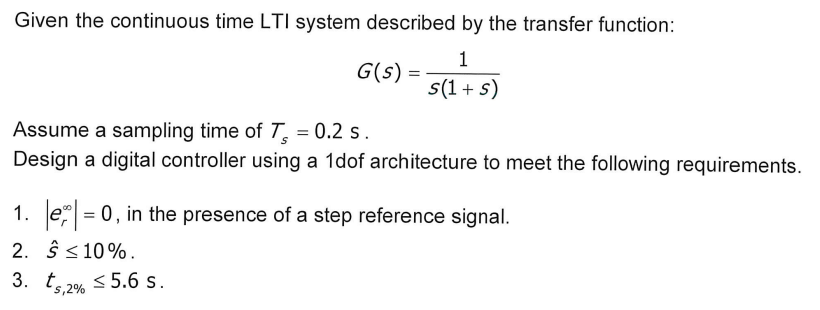

s = tf('s');
ts = 0.2;
z = tf('z',ts);
G_cont = 1/(s*(1+s));

la funzione `c2d` mi trasforma una funzione da continua in discreta

G_disc = zpk(c2d(G_cont,ts,'zoh'))

G_disc =
 
  0.018731 (z+0.9355)
  -------------------
   (z-1) (z-0.8187)
 
Sample time: 0.2 seconds
Discrete-time zero/pole/gain model.



[z_G, p_G, k_G] = zpkdata(G_disc,'v')

z_G = -0.9355

p_G =     1.0000
    0.8187


k_G = 0.0187

Definisco i polinomi $B\left(z\right),A\left(z\right)$ $\to$ $G\left(z\right)=\frac{B\left(z\right)}{A\left(z\right)}$

B = k_G*[1 -z_G];
A = conv([1 -p_G(1)], [1 -p_G(2)]);

Per garantire $|e_r^{\infty } |=0$ è necessario un polo in 1 in $L\left(z\right)=C\left(z\right)\cdot G\left(z\right)$

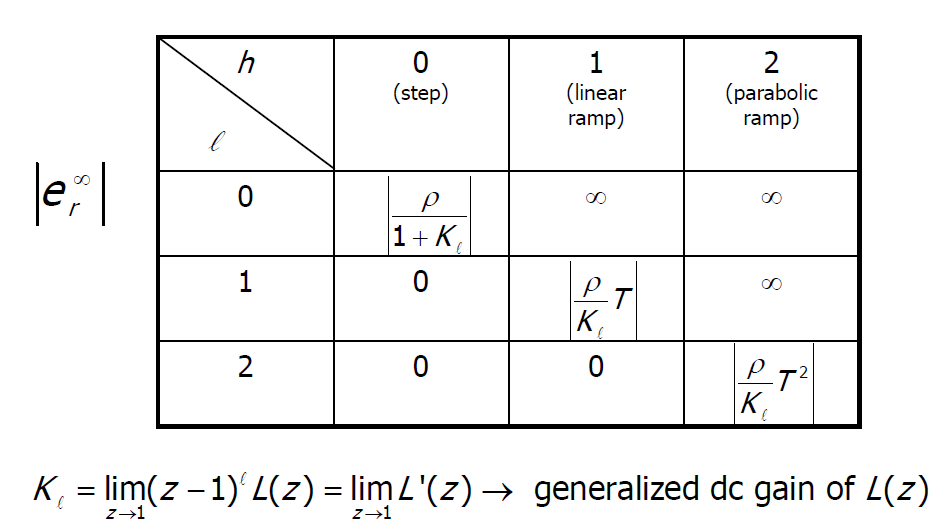

qui $G\left(z\right)$ ha un polo in 1 quindi non devo aggiungerne in $C\left(z\right)=\frac{S\left(z\right)}{R\left(z\right)}$ 

Impongo i requisiti per zeta per soddisfare $\hat{s} \le 10%$ $\to \zeta \ge \frac{|\log \left(\hat{s} \right)|}{\sqrt{\pi^2 +\log^2 \left(\hat{s} \right)}}$

s_hat = 0.1;
zeta = abs(log(s_hat))/(sqrt(pi^2 + (log(s_hat))^2))

zeta = 0.5912

Per soddisfare il requisito sul settling time $t_{s,2%} \le 5\ldotp 6s\to \omega_n \ge \frac{4}{\zeta \cdot t_{s,2%} }$:

t_s2 = 5.6;
wn = 4/(zeta*t_s2)

wn = 1.2083

## **PARTE 1 : CANCELLO TUTTI I POLI E GLI ZERI INDISCRIMINATAMENTE (non considero i requisiti e la cardioide)**

Cancello tutti gli zeri e i poli stabili con $|z|\le 1$ e definisco i polinomi $A^+ \left(z\right),A^- \left(z\right),B^+ \left(z\right),B^- \left(z\right)$:

A_plus = [1 -p_G(2)]            %poli da eliminare

A_plus =     1.0000   -0.8187


A_minus = 1                     %poli da mantenere

A_minus = 1

B_plus = [1 -z_G]               %zeri da eliminare

B_plus =     1.0000    0.9355


B_minus = k_G                   %zeri da mantenere

B_minus = 0.0187

Le condizioni sui gradi sono: 


$$\begin{array}{l}
\deg \left(S^{\prime } \left(z\right)\right)=l+\deg \left(A^- \left(z\right)\right)-1=l_1 +l_2 +\deg \left(A^- \left(z\right)\right)-1=1+0+0-1=0\\
\deg \left(R^{\prime } \left(z\right)\right)=\deg \left(A^{\prime } \left(z\right)\right)-\deg \left(B^+ \left(z\right)\right)+l_1 -1=\;1-1+1-1=0\\
\deg \left(A_m \left(z\right)\right)=l+\deg \left(A^{\prime } \left(z\right)\right)+\deg \left(A^- \left(z\right)\right)+l_1 -\deg \left(B^+ \left(z\right)\right)-1=1+1+0+1-1-1=1\;\left(\mathrm{un}\;\mathrm{solo}\;\mathrm{polo}\;\mathrm{da}\;\mathrm{piazzare}\;\mathrm{in}\;C\left(z\right)\right)
\end{array}$$
 


$$C\left(z\right)=\frac{A^+ \left(z\right)\cdot S^{\prime } \left(z\right)}{B^+ \left(z\right)\cdot R^{\prime } \left(z\right)}$$


Assegno un solo polo in $z=-\zeta \omega_n =-0\ldotp 7143$

p1c = -zeta*wn; %polo in continua
p1 = exp(ts*p1c)

p1 = 0.8669


$$A_m \left(z\right)\;=z-0\ldotp 8669$$


Am = poly(p1)

Am =     1.0000   -0.8669


L'equazione diofantea è: $\left(z-1\right)A^- \left(z\right)R^{\prime } \left(z\right)+B^- \left(z\right)S^{\prime } \left(z\right)=A_m \left(z\right)\to \left(z-1\right)\cdot r_0 +0\ldotp 018731\cdot s_0 =z-0\ldotp 8669\to p_o =1,s_0 =7,1071$, creo la matrice $M_s$:

A_dioph = conv([1 -1], A_minus);
B_dioph = B_minus;
M_s = [[A_dioph(:)], [0;B_dioph(:)]]

M_s =     1.0000         0
   -1.0000    0.0187


Gamma = Am';
theta = M_s\Gamma

theta =     1.0000
    7.1071


R1 = theta(1)'

R1 = 1

S1 = theta(2)'

S1 = 7.1071

R = conv(B_plus, R1);
S = conv(A_plus, S1);
C = zpk(tf(S,R,ts))

C =
 
  7.1071 (z-0.8187)
  -----------------
     (z+0.9355)
 
Sample time: 0.2 seconds
Discrete-time zero/pole/gain model.



W= minreal(zpk((C*G_disc)/(1+ C*G_disc)),1e-3)

W =
 
   0.13312
  ----------
  (z-0.8669)
 
Sample time: 0.2 seconds
Discrete-time zero/pole/gain model.



W3 = minreal(zpk(C/(1+ C*G_disc)),1e-3)

W3 =
 
  7.1071 (z-1) (z-0.8187)
  -----------------------
   (z-0.8669) (z+0.9355)
 
Sample time: 0.2 seconds
Discrete-time zero/pole/gain model.



%figure
%step(W)

La condizione sul tempo di settling non è rispettata $\left(t_{s,2%} =5,755s\right)>5\ldotp 6s\to \mathrm{serve}\;\mathrm{effettuare}\;\mathrm{cancellazioni}\;\mathrm{solo}\;\mathrm{nella}\;\mathrm{zona}\;\mathrm{data}\;\mathrm{dai}\;\mathrm{requisiti}\;\mathrm{di}\;\zeta$. 

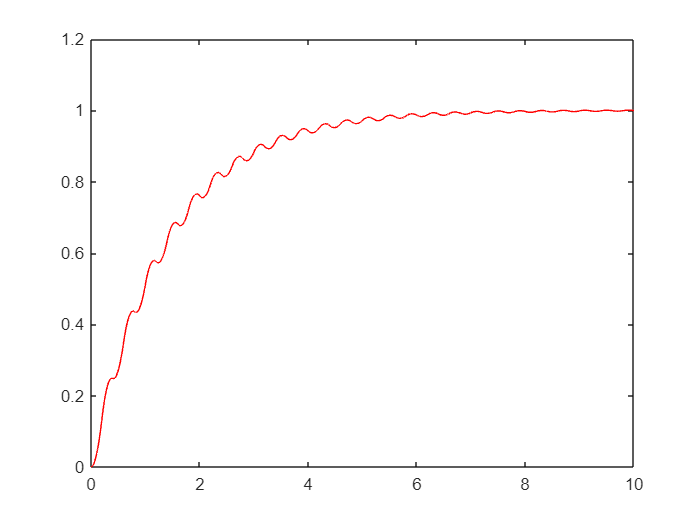

out = sim('DC6a_es');
figure
plot(out.y.time, out.y.data, 'r') %simulazione con G(s)

## PARTE 2: cancellazione dei soli poli e zeri stabili ( nella cardioide )

Disegno la cardioide

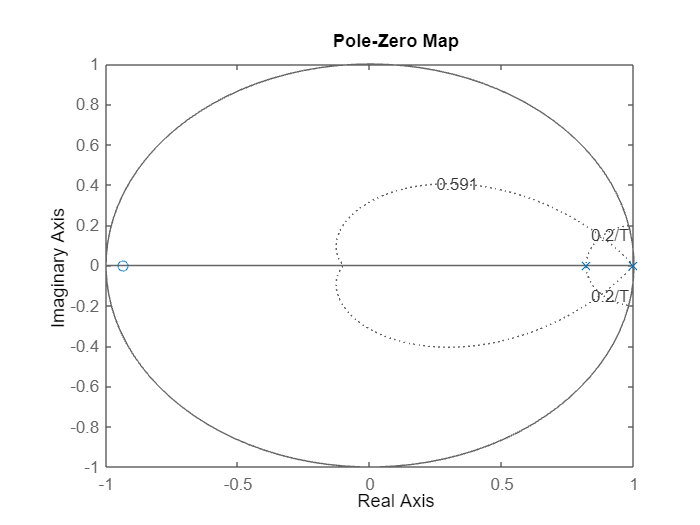

figure
pzmap(G_disc)
zgrid(zeta,ts)

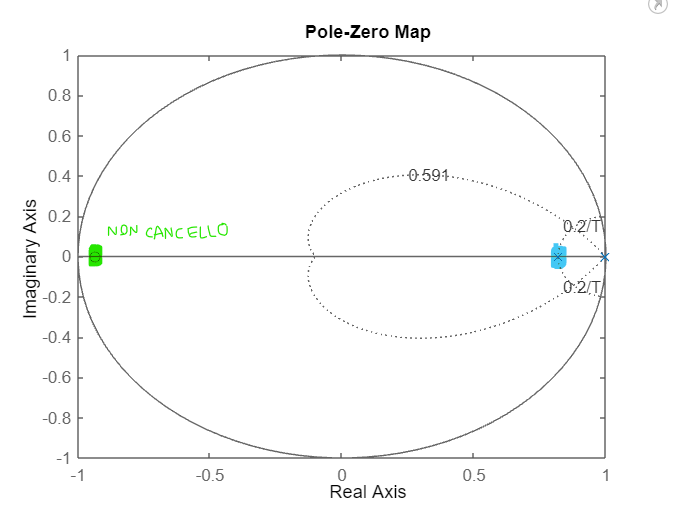

devo cancellare solo il polo azzurro

A1_plus = [1 -p_G(2)];
A1_minus = 1;
B1_plus = 1; 
B1_minus = conv(k_G, [1 -z_G]);

Questa volta le condizioni sui gradi sono: 


$$\begin{array}{l}
\deg \left(S^{\prime } \left(z\right)\right)=0\\
\deg \left(R^{\prime } \left(z\right)\right)=1\\
\deg \left(A_{m\left(\right.} \left(z\right)\right)=2\;\left(\mathrm{devo}\;\mathrm{scegliere}\;2\;\mathrm{poli}\;\mathrm{nella}\;\mathrm{zona}\;\mathrm{concessa}\;\mathrm{dai}\;\mathrm{requisiti}\;\mathrm{di}\;\mathrm{zeta}\right)
\end{array}$$


P1c = -zeta*wn + 1i*wn*sqrt(1 - zeta^2);
P2c = -zeta*wn -1i*wn*sqrt(1- zeta^2);
P1 = exp(ts*P1c)

P1 = 0.8505 + 0.1679i

P2 = exp(ts*P2c)

P2 = 0.8505 - 0.1679i

A1m = poly([P1 P2])

A1m =     1.0000   -1.7009    0.7515


A1_dioph = conv([1 -1], A1_minus)

A1_dioph =      1    -1


B1_dioph = B1_minus

B1_dioph =     0.0187    0.0175


M1_s = [[A1_dioph(:);0], [0; A1_dioph(:)], [0; B1_dioph(:)]]

M1_s =     1.0000         0         0
   -1.0000    1.0000    0.0187
         0   -1.0000    0.0175


gamma1 = A1m';
theta1 = M1_s\gamma1

theta1 =     1.0000
   -0.7270
    1.3943


R11 = theta1(1:2)'

R11 =     1.0000   -0.7270


S11 = theta1(3)'

S11 = 1.3943

R1_fin = R11

R1_fin =     1.0000   -0.7270


S1_fin = conv(A1_plus, S11);
C1 = zpk(tf(S1_fin,R1_fin,ts))

C1 =
 
  1.3943 (z-0.8187)
  -----------------
      (z-0.727)
 
Sample time: 0.2 seconds
Discrete-time zero/pole/gain model.



W = minreal(zpk(feedback(C*G_disc,1)),1e-2)

W =
 
   0.13312
  ----------
  (z-0.8669)
 
Sample time: 0.2 seconds
Discrete-time zero/pole/gain model.



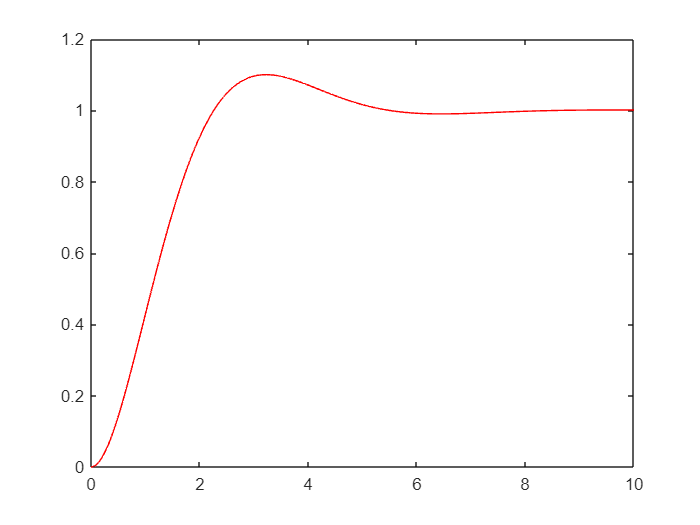

out1 = sim('DC6b_es');
figure
plot(out1.y.time, out1.y.data, 'r')

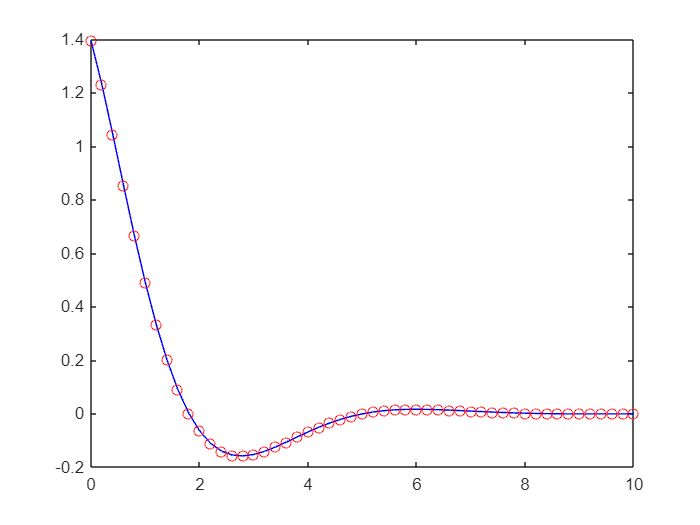

plot(out1.u.time, out1.u.data, 'b')
hold on
plot(out1.u.time, out1.u.data, 'ro')

## `PARTE 3: REQUISITO SU `$\mathit{\mathbf{u}}\left(\mathit{\mathbf{t}}\right)$